# Fiche systèmes stables standards

## Système d'ordre 1

Equation différentielle :


$$\tau \dot y = y + k u$$$


Représentation d'état :


$$\left\{\matrix{ \dot x = A x + B u \cr y = Cx + D u  }$$
 

avec $A=-\frac{1}{\tau}, B = -\frac{k}{\tau}, C = 1, D = 0$

Fonction de transfert :


$$\frac{Y(s)}{U(s)}=\frac{k}{\tau s+1}$$


### Analyse :

Pôle = $-\frac{1}{\tau}$

Stable si $\tau>0$

Si stable :

    Temps de réponse = $3\tau$

    Constante de temps  = $\tau$

    Gain statique $k$

### Réponses du système :

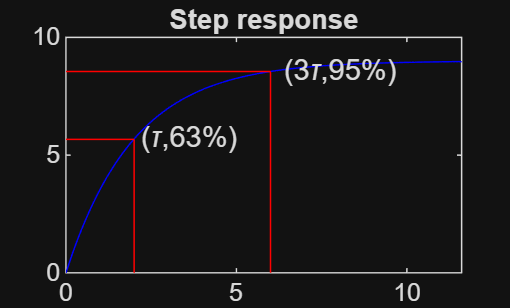

K = 9;
tau = 2;
F = tf(K,[tau 1]);
order1Step(K, tau);

stepinfo(F,"SettlingTimeThreshold",0.05)

ans = struct with fields:
         RiseTime: 4.3940
    TransientTime: 5.9916
     SettlingTime: 5.9916
      SettlingMin: 8.1405
      SettlingMax: 8.9941
        Overshoot: 0
       Undershoot: 0
             Peak: 8.9941
         PeakTime: 14.6444


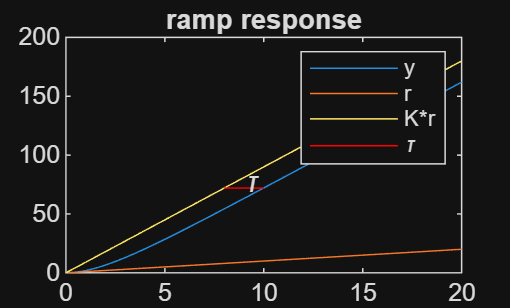

order1Ramp(K, tau);

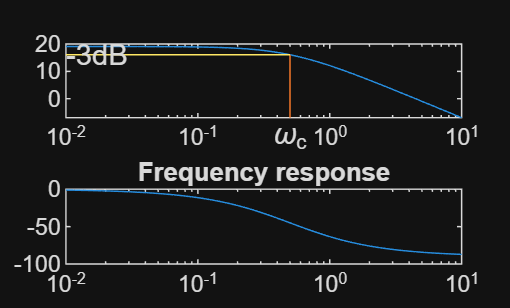

order1Freq(K, tau);

wc = bandwidth(F,-3)

wc = 0.4988

### Identification :

La réponse a une pente non nulle à l'orgine et ne présente pas d'oscillations. Attention d'autres systèmes plus complexes peuvent ressembler à cette réponse.

On peut déterminer les coefficient du modèle à partir de ses réponses.

Dans le cas de la réponse indicielle (à un échelon), on regarde la valeur finale et on en déduit $K$ puis on regarde le temps mis pour atteindre 63% pour en déduire $\tau$.

Dans le cas fréquentiel, on peut constater que la pente finale est de -20dB par décades. La pulsation de coupure donne $1/\tau$. Le gain statique est déduit en regardant le gain aux petites fréquences $20log(K)$.

## Système d'ordre 2

Dans le cas stable, il peut s'écrire avec $\omega_n >0$ la pulsation naturelle et $\xi>0$le coefficient d'amortissement :

Equation différentielle : $\ddot y + 2\xi \omega_n \dot y + \omega_n^2 y=ku$ avec $\omega_n >0$ la pulsation naturelle et $\xi>0$le coefficient d'amortissement.

Représentation d'état :


$$\left\{\matrix{ \dot x = A x + B u \cr y = Cx + D u  }$$
 

avec $A=\pmatrix{-2*\xi\omega_n & \omega_n^2 \cr 1 & 0}, B = \pmatrix{k*\omega_n^2 \cr 0}, C = \pmatrix{1 & 0}, D = 0$

Fonction de transfert :


$$\frac{Y(s)}{U(s)}=\frac{k\omega_n^2}{s^2 + 2\xi\omega_n s+ \omega_n^2 }$$


**Attention :** Certains systèmes du second ordre instables ne peuvent pas s'écrirent sous cette forme.

### Analyse :

Les pôles sont : $p_{1,2} = -\xi \omega_n \pm \omega_n\sqrt{\xi^2-1}$ dans le cas mal amorti $\xi<1$ ils sont complexes conjugués :$p_{1,2} = -\xi \omega_n \pm \omega_n i \sqrt{1-\xi^2}$

Le gain statique est $K$.

### Réponses du système :

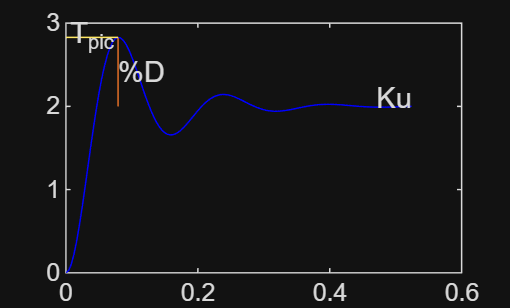

K=2;
w=41;
xi=0.27;
F = tf(K*w^2,[1 2*xi*w w*w]);
order2Step(K, xi, w);

stepinfo(F,"SettlingTimeThreshold",0.05)

ans = struct with fields:
         RiseTime: 0.0315
    TransientTime: 0.2596
     SettlingTime: 0.2596
      SettlingMin: 1.6569
      SettlingMax: 2.8286
        Overshoot: 41.4288
       Undershoot: 0
             Peak: 2.8286
         PeakTime: 0.0790


Temps de réponse : 

    $T_r \approx 3/(\xi\omega_n)$ si $\xi<1$

    $T_r = 2.9/(\omega_n)$ si $\xi=0.7$

    $T_r = 5/\omega_n$ si $\xi \approx 1$

    sinon $T_r \approx T_r(pôle\_dominant)$

Dépassement : $\%D=\frac{max(y)-y(\infty)}{y(\infty)} = e^{\frac{-\pi\xi}{\sqrt{1-\xi^2}}}$

Pour $\xi=0.7$ on a $\%D = 5\%$

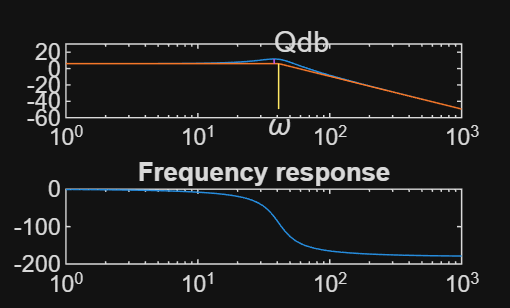

order2Freq(K, xi, w);

wc = bandwidth(F,-3)

wc = 60.3628

Qdb = getPeakGain(F)

Qdb = 3.8465

Pulsation propre : $\omega_p = \omega_n \sqrt{1-\xi^2}$, 


$$T_{pic} =T_p/2 = {\pi}/{\omega_p}$$


### Identification :

La réponse a une pente nulle à l'orgine et peut présenter des oscillations. Attention beacoup de systèmes peuvent ressembler à cette réponse.

On peut déterminer les coefficient du modèle à partir de ses réponses.

Dans le cas de la réponse indicielle (à un échelon), on regarde la valeur finale et on en déduit $K$. Pour les autres coefficients, on peut les déduires facilement dans le cas où un dépassement est présent en utilisant la formule de $\%D$ pour déduire l'amortissement puis la formule de $\omega_p/2$ pour déduire la pulsation naturelle. Dans le cas sans dépassement, des techniques plus avancées doivent être utilisées.

Dans le cas fréquentiel, on peut constater que la pente finale est de -40dB par décades. La pulsation naturelle peut être retrouvée en traçant les asymtotes du lieu. On retrouve l'amortissement en utilisant des abaques. Le gain statique est déduit en regardant le gain aux petites fréquences $20log(K)$.

## Utilisation

La connaissance des réponses des systèmes d'odre 1 et 2 seront utiles par la suite pour : 

- Identifier les coefficients des systèmes simples (stables et ordre réduits). On peut obtenir ces valeurs en mesurant des points caractéristiques mais en général on préfèrera des méthodes numériques. 

- Avoir une idée du modèle idéal que l'on pourrait souhaiter en boucle fermée. 

- Construire des filtres pour limiter les bruits dans certains cannaux.

function [t, y] = order1Step(K, tau)
F = tf(K,[tau 1]);
[y,t] =step(F);
figure;
plot(t,y,'b');
hold on;
plot([0 tau],K*0.63*[1 1],'r-');
plot([tau tau],K*0.63*[1 0],'r-');
plot([0 3*tau],K*0.95*[1 1],'r-');
plot([3*tau 3*tau],K*0.95*[1 0],'r-');
text(tau*1.05,K*0.63,'(\tau,63%)',"HorizontalAlignment","Left","Interpreter","tex")
text(3*tau*1.05,K*0.95,'(3\tau,95%)',"HorizontalAlignment","Left","Interpreter","tex")
title('Step response')
end

function [t, y] = order1Ramp(K, tau)
F = tf(K,[tau 1]);
t = linspace(0,10*tau,100);
[y,t] =lsim(F,t,t);
figure;
plot(t,y);
hold on;
plot(t,t);
plot(t,K*t);
plot([4*tau 5*tau],K*4*tau*[1 1],'r-');
text(4.5*tau,K*4.2*tau,'\tau')
title('ramp response')
legend('y','r','K*r','\tau')
end

function order1Freq(K, tau)
    F = tf(K,[tau 1]);
    figure
    [mag, phase, W] = bode(F);
    mag20 = 20*log10(mag(:));
    subplot(2,1,1)
    semilogx(W,mag20);hold on
    plot(1/tau*[1 1],[(mag20(1))-3,mag20(end)])
    plot([W(1) 1/tau],((mag20(1))-3)*[1 1])
    text(W(1),max(mag20)-3,'-3dB')
    text(1/tau,mag20(end),'\omega_c','HorizontalAlignment',"center","VerticalAlignment","top")
    subplot(2,1,2)
    semilogx(W,phase(:));hold on
    title('Frequency response')
end

function order2Freq(K, xi, wn)
    figure
    F = tf(K*wn^2,[1 2*xi*wn wn*wn]);
    [mag, phase, W] = bode(F);
    mag20 = 20*log10(mag(:));
    subplot(2,1,1)
    semilogx(W,mag20);hold on
    plot([W(1) wn W(end)],mag20(1)-[0 0 2*20*log10(W(end)/wn)])
    plot(wn*[1 1],[(mag20(1)),mag20(end)])
    [~,idx] = max(mag20);
    plot(W(idx)*[1 1],[mag20(idx) mag20(1)])
    
    text(W(idx),max(mag20),'Qdb','HorizontalAlignment',"left","VerticalAlignment","bottom")
    
    text(wn,mag20(end),'\omega','HorizontalAlignment',"center","VerticalAlignment","top")
    
    yl = ylim;
    ylim([yl(1) yl(2)+10]);
    
    subplot(2,1,2)
    semilogx(W,phase(:));hold on
    title('Frequency response')
   

end

function order2Step(K, xi, wn)
F = tf(K*wn^2,[1 2*xi*wn wn*wn]);
[y,t] =step(F);
figure;
plot(t,y,'b');
hold on;
[ymax,idx]=max(y);
if xi <1
    plot(t(idx)*[1 1],[y(end) ymax])
    text(t(idx), (ymax+y(end))/2,'%D')
    plot(t(idx)*[0 1],[ymax ymax])
    text(t(idx)*0.5, ymax*1.0,'T_{pic}',"HorizontalAlignment","center")
end
text(t(end),y(end)*1.05,'Ku',"HorizontalAlignment","right")
end